s0_add_paths

## The stimuli

dataset = 1;
fname = sprintf('stimuli-dataset0%1d', dataset);
path=fullfile(stdnormRootPath, 'Data', 'Stimuli', fname);
load(path, 'stimuli');
stim = double(stimuli);

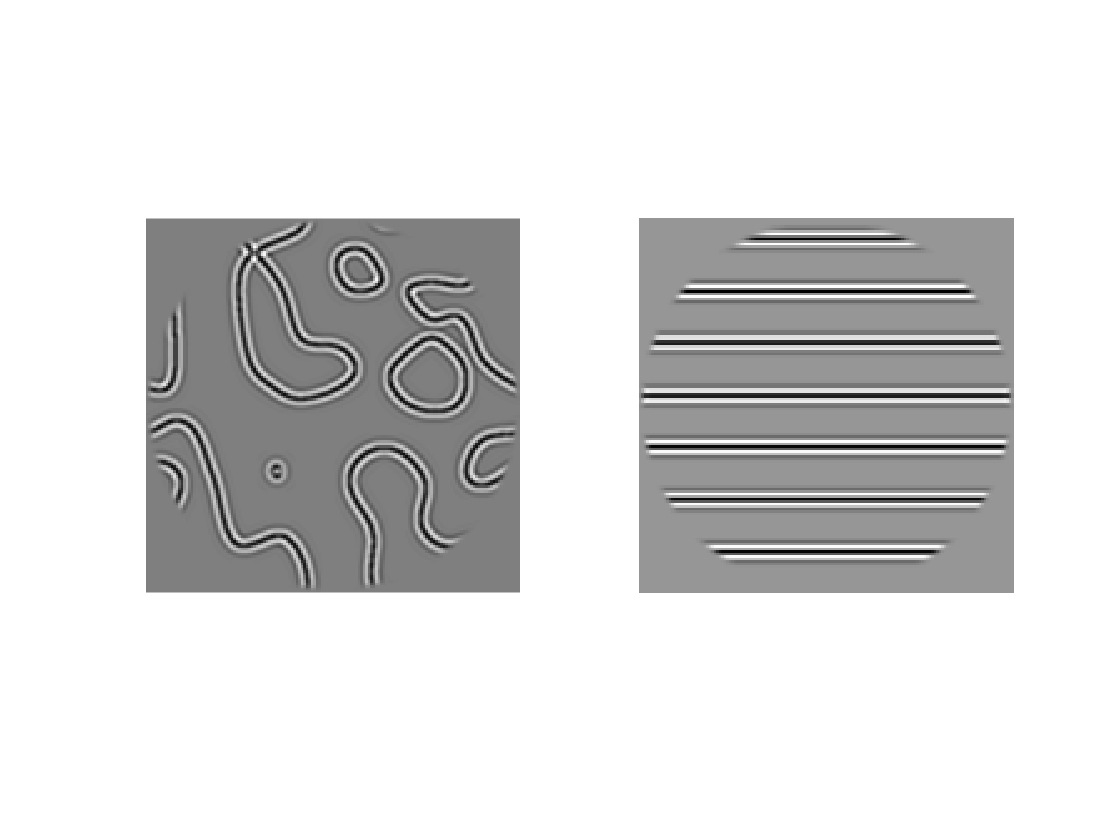

snake   = stim(:, :, 1, 3);
grating = stim(:, :, 1, 8);
figure();
subplot(1, 2, 1);
imshow(snake, [])
subplot(1, 2, 2);
imshow(grating, [])

## The parameters

% the frequency vectors
filter_cpds = [1, 3];  
% the orientation vectors 
radians     = linspace(0, pi, 9);
orients     = radians(1:end-1);

% other parameters 
numpix     = size(stim, 1);
pixperdeg  = numpix / 12.5;
support    = 6;  % cycle per filter 
ppc        = pixperdeg ./ filter_cpds

ppc =     12     6     4     3


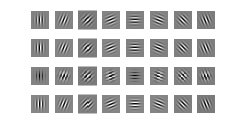


% create filters
[Gabor_c, Gabor_s]=makeGaborFilter(ppc, orients, support);

% visualize 
nR = size(Gabor_c, 2); nC = size(Gabor_c, 1);
for k= 1:1
    for j = 1:nR
        for i = 1:nC
            subplot(nR, nC, (j-1)*nC+i)
            switch k
                case 1; imshow(Gabor_c{i, j}, []); 
                case 2; imshow(Gabor_s{i, j}, []); 
            end
        end
    end
end

## What to do with the filters

## 
$$E(x,y,\theta) = \sum_{\phi, f}\left(\sum_{x',y'}F(x',y',\theta,f, \phi) I(x-x',y-y')\right)^2$$


## Solutions

- larger image 

- Filter the original image and downsample the energy output to 150 px. 

- Compare the ratios of the snakes at the density group 

- Sum over orientation and space, see the energy distribution over frequencies, expect highest value at f=3. 